warning('off')

toy_samples = 50;
nb_inputs = 2;
nb_outputs = 2;

bf = {@theta1, @theta2, @theta3, @theta4, @theta5, @theta6, @theta7, @theta8, @theta9, @theta10};
r = 3;
sampling_points = randn(nb_inputs, toy_samples);

Jac = zeros(nb_outputs, nb_inputs, toy_samples);
F = zeros(nb_outputs, toy_samples);
for i=1:toy_samples
    point = dlarray(sampling_points(:,i)');
    [F(1,i), Jac(1,:,i)] = dlfeval(@f1, point);
    [F(2,i), Jac(2,:,i)] = dlfeval(@f2, point);
end

bf1 = {@theta1, @theta2, @theta3, @theta4, @theta5};%, @theta6, @theta7, @theta8, @theta9, @theta10};
bf1d = {@theta1d, @theta2d, @theta3d, @theta4d, @theta5d};

r = 21;
[W_toy, V_toy, H_toy, Z_toy, c_toy] = CMTF(Jac, F, bf1, bf1d, r, sampling_points);

i = 1

JacError = 0.5981

Ferror = 0.5938

i = 2

JacError = 0.5177

Ferror = 0.4752

i = 3

JacError = 0.4812

Ferror = 0.4394

i = 4

JacError = 0.4657

Ferror = 0.4247

i = 5

JacError = 0.4586

Ferror = 0.4144

i = 6

JacError = 0.4715

Ferror = 0.4466

i = 7

JacError = 0.4681

Ferror = 0.4518

i = 8

JacError = 0.4612

Ferror = 0.4466

i = 9

JacError = 0.4599

Ferror = 0.4493

i = 10

JacError = 0.4561

Ferror = 0.4443

i = 11

JacError = 0.5946

Ferror = 0.6214

i = 12

JacError = 0.7587

Ferror = 1.0552

i = 13

JacError = 0.5548

Ferror = 0.5167

i = 14

JacError = 0.5160

Ferror = 0.5078

i = 15

JacError = 0.6942

Ferror = 0.6236

i = 16

JacError = 1.1608

Ferror = 0.9582

i = 17

JacError = 3.4694

Ferror = 1.8950

i = 18

JacError = 0.9579

Ferror = 0.6058

i = 19

JacError = 1.0838

Ferror = 0.6999

i = 20

JacError = 2.7124

Ferror = 1.1491

i = 21

JacError = 1.4831

Ferror = 0.8282

i = 22

JacError = 1.4250

Ferror = 0.7423

i = 23

JacError = 2.9352

Ferror = 1.0521

i = 24

JacError = 2.3459

Ferror = 0.9435

i = 25

JacError = 4.8434

Ferror = 1.8073

i = 26

JacError = 1.9889

Ferror = 0.8432

i = 27

JacError = 2.3371

Ferror = 0.9713

i = 28

JacError = 1.3166

Ferror = 0.7113

i = 29

JacError = 1.8388

Ferror = 0.8266

i = 30

JacError = 1.3787

Ferror = 0.7030

i = 31

JacError = 16.2924

Ferror = 9.0939

i = 32

JacError = 1.7372

Ferror = 0.7825

i = 33

JacError = 1.6091

Ferror = 0.8342

i = 34

JacError = 9.9549

Ferror = 3.1225

i = 35

JacError = 1.1582

Ferror = 0.5649

i = 36

JacError = 1.3504

Ferror = 0.5359

i = 37

JacError = 0.8354

Ferror = 0.4921

i = 38

JacError = 1.7119

Ferror = 0.8810

i = 39

JacError = 1.0624

Ferror = 0.6384

i = 40

JacError = 0.8276

Ferror = 0.4011

i = 41

JacError = 0.7893

Ferror = 0.7217

i = 42

JacError = 0.7826

Ferror = 0.4345

i = 43

JacError = 0.8752

Ferror = 0.5620

i = 44

JacError = 1.0239

Ferror = 0.4691

i = 45

JacError = 0.6297

Ferror = 0.3776

i = 46

JacError = 0.6259

Ferror = 0.4458

i = 47

JacError = 0.7370

Ferror = 0.4962

i = 48

JacError = 0.6722

Ferror = 0.5163

i = 49

JacError = 0.6044

Ferror = 0.3949

i = 50

JacError = 0.5307

Ferror = 0.3387

err = 0.5307

U = {W_toy, V_toy, H_toy};
frob(cpdres(Jac, U)) / frob(Jac)

ans = 0.7285

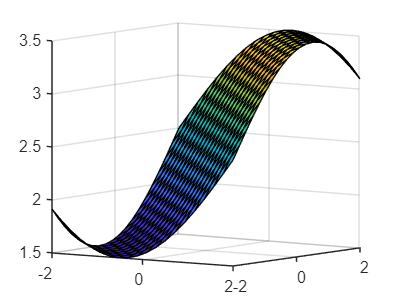

x = linspace(-2,2,20);
y = x';
z = zeros(20);
zb = zeros(20,20,2);
for i=1:20
    for j=1:20
        point = dlarray([x(i), y(j)]);
        [z(i,j), ~] = dlfeval(@f1, point);
        zb(i,j,:) = fbar([x(i); y(j)], W_toy, V_toy, c_toy);
    end
end

% Origineel
surf(x,y,z)
view([35.05 6.20])

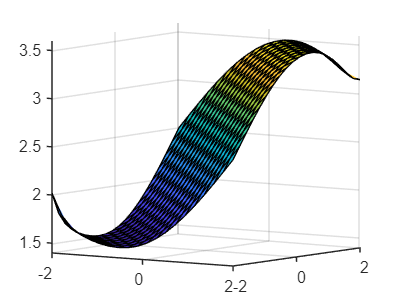

% Benadering
surf(x,y,zb(:,:,1))
view([35.05 6.20])
zlim([1.4 3.6])

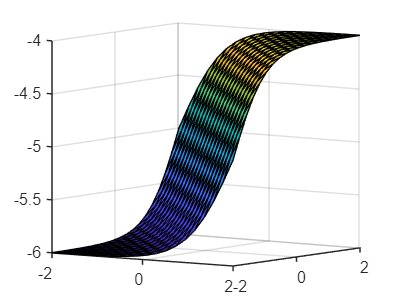


z = zeros(20);
for i=1:20
    for j=1:20
        point = dlarray([x(i), y(j)]);
        [z(i,j), ~] = dlfeval(@f2, point);
    end
end

% Origineel
surf(x,y,z)
view([35.05 6.20])

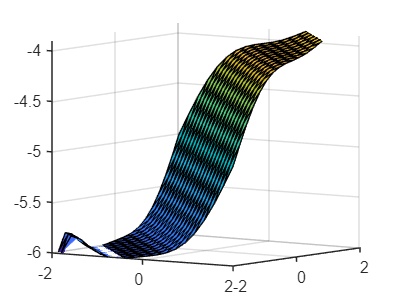

% Benadering
surf(x,y,zb(:,:,2))
view([35.05 6.20])
zlim([-6 -3.9])

function [f,grad] = f1(x)
    f = 2.5 + sin(0.2 * pi * (x(1) + x(2)));
    grad = dlgradient(f,x);
end

function [f] = fbar(u, W, V, c_toy)
    P = zeros(3,1);
    x = V' * u;
    for i=1:3
        P(i,1) = c_toy((11* (i - 1)) + 1) + ...
                 c_toy((11* (i - 1)) + 2) * x(i) + ...
                 c_toy((11* (i - 1)) + 3) * x(i)^2 + ...
                 c_toy((11* (i - 1)) + 4) * x(i)^3 + ...
                 c_toy((11* (i - 1)) + 5) * x(i)^4 + ...
                 c_toy((11* (i - 1)) + 6) * x(i)^5 + ...
                 c_toy((11* (i - 1)) + 7) * x(i)^6 + ...
                 c_toy((11* (i - 1)) + 8) * x(i)^7 + ...
                 c_toy((11* (i - 1)) + 9) * x(i)^8 + ...
                 c_toy((11* (i - 1)) + 10) * x(i)^9 + ...
                 c_toy((11* (i - 1)) + 11) * x(i)^10;
    end
    f = W * P;
end

function [f,grad] = f2(x)
    f = -5 + tanh(sum(x));
    grad = dlgradient(f,x);
end

% function [f,grad] = theta1(x)
%     f = x;
%     grad = dlgradient(f,x);
% end
% 
% function [f,grad] = theta2(x)
%     f = x^2;
%     grad = dlgradient(f,x);
% end
% 
% function [f,grad] = theta3(x)
%     f = x^3;
%     grad = dlgradient(f,x);
% end
% 
% function [f,grad] = theta4(x)
%     f = x^4;
%     grad = dlgradient(f,x);
% end
% 
% function [f,grad] = theta5(x)
%     f = x^5;
%     grad = dlgradient(f,x);
% end

function [f] = theta1(x)
    f = x;
end

function [f] = theta1d(x)
    f = 1;
end

function [f] = theta2(x)
    f = x^2;
end

function [f] = theta2d(x)
    f = 2*x;
end

function [f] = theta3(x)
    f = x^3;
end

function [f] = theta3d(x)
    f = 3*x^2;
end

function [f] = theta4(x)
    f = x^4;
end

function [f] = theta4d(x)
    f = 4*x^3;
end

function [f] = theta5(x)
    f = x^5;
end

function [f] = theta5d(x)
    f = 5*x^4;
end

function [f,grad] = theta6(x)
    f = x^6;
    grad = dlgradient(f,x);
end

function [f,grad] = theta7(x)
    f = x^7;
    grad = dlgradient(f,x);
end

function [f,grad] = theta8(x)
    f = x^8;
    grad = dlgradient(f,x);
end

function [f,grad] = theta9(x)
    f = x^9;
    grad = dlgradient(f,x);
end

function [f,grad] = theta10(x)
    f = x^10;
    grad = dlgradient(f,x);
end